x = 1:10;
y = x.^2;
kernel = [1, -1];

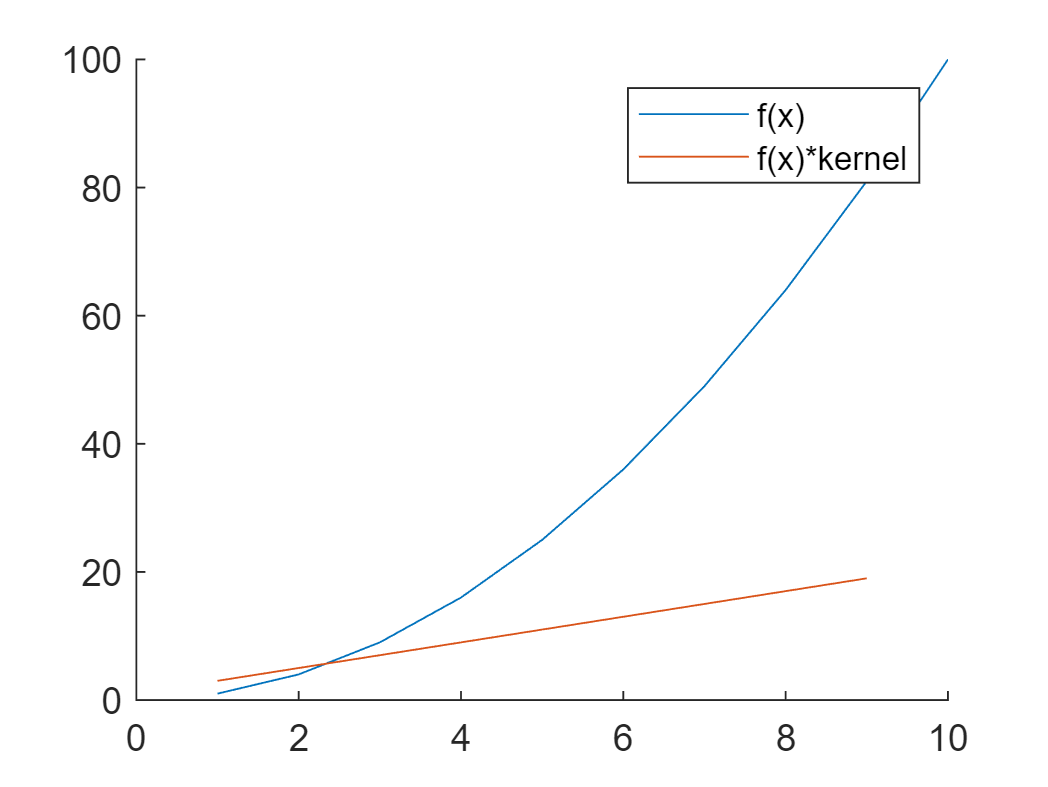

y_conv = conv(y,kernel,"same");
hold on
plot(x, y, x(1:end-1), y_conv(1:end-1))
legend(["f(x)", "f(x)*kernel"])
hold off

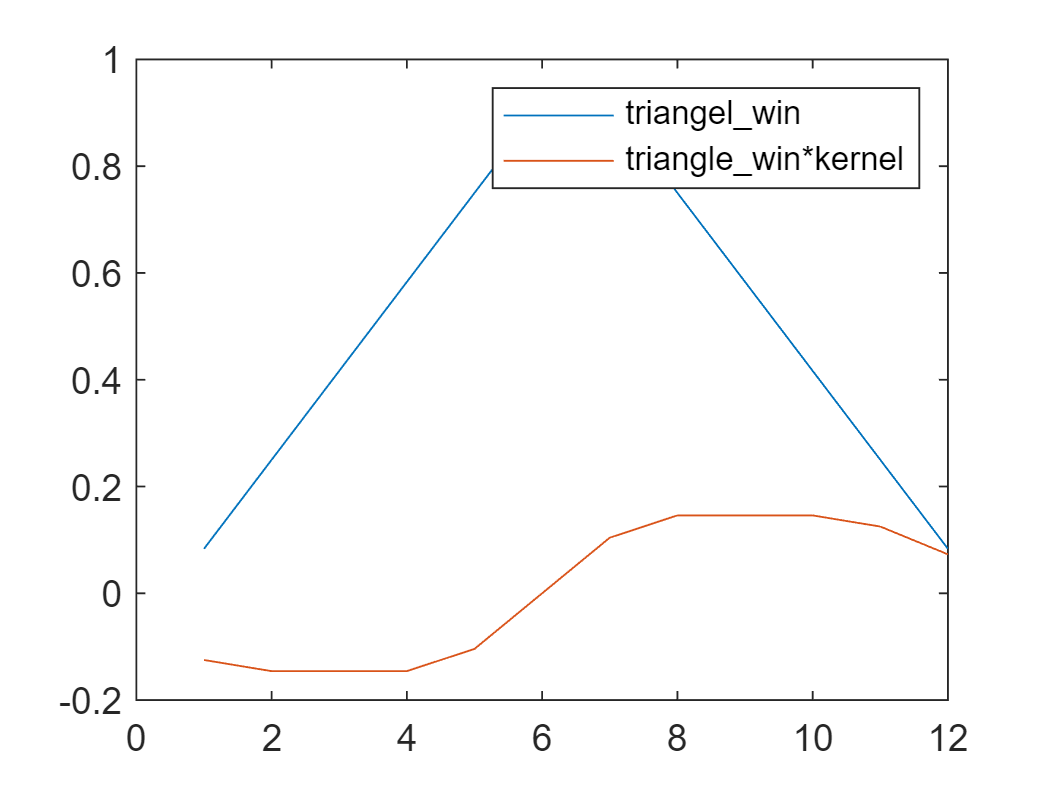

x = 1:12;
y2 = triang(200*.06);
kernel2 = [-2,-1,1,2]/8;
y_conv2 = conv(y2, kernel2, "same");
plot(x, y2, x, y_conv2)
legend(["triangel\_win", "triangle\_win*kernel"])

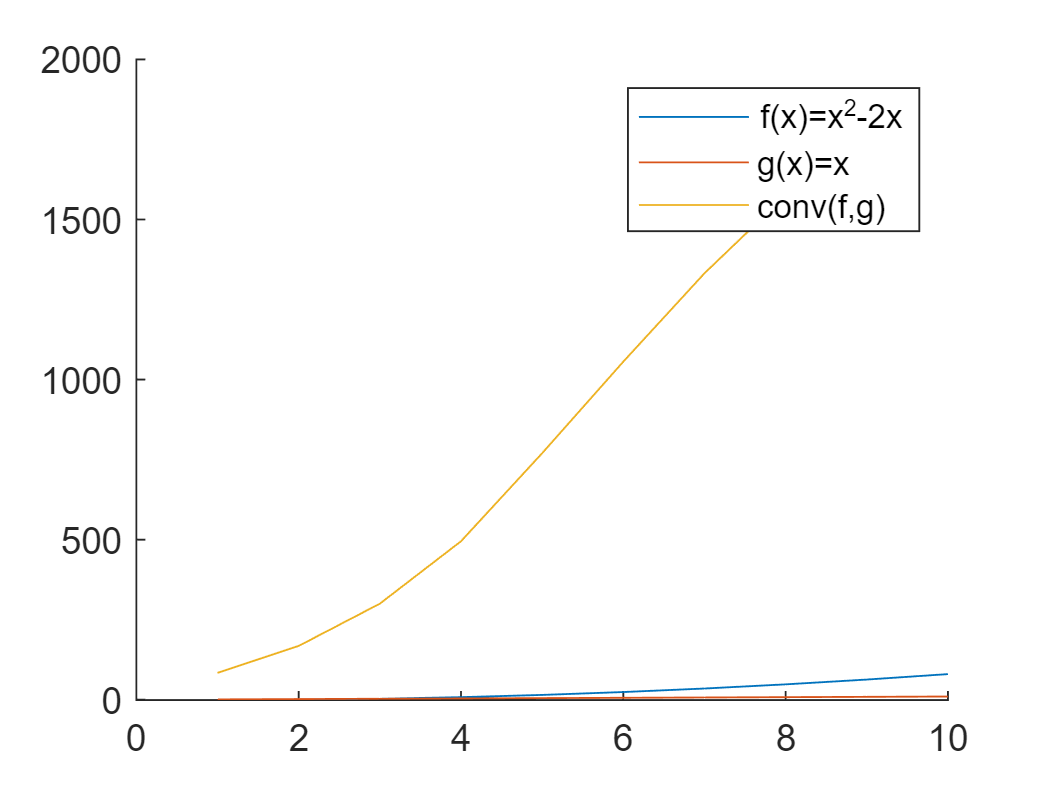

x = 1:10;
y1=x.^2-2*x;
y2=x;
y_conv3 = conv(y1,y2,"same");
figure(3)
hold on
plot(x,y1,x,y2,x(1:end-1),y_conv3(1:end-1));
% plot(x(1:end-1),y_conv3(1:end-1));
legend(["f(x)=x^2-2x", "g(x)=x","conv(f,g)"]) %,"conv(f,g)"
hold off